# Deep Learning In 6 Lines of Code

## Load Pre-trained CNN

Pre-trained CNNs are deep networks that are already trained on thousands of different images. They can work for classification "right out of the box." 

There are several networks available from our [Add-Ons](https://www.mathworks.com/add-ons/ALEXNET/) section under the home tab. We will use a pretrained model called [AlexNet](https://en.wikipedia.org/wiki/AlexNet), which is trained on a subsection of the [ImageNet](http://www.image-net.org/) database. It classifies images of 1000 different categories. 

% Load the AlexNet neural network
net = alexnet;

% View the network layers and connections
% analyzeNetwork(net)

## Classify Image of "Peppers"

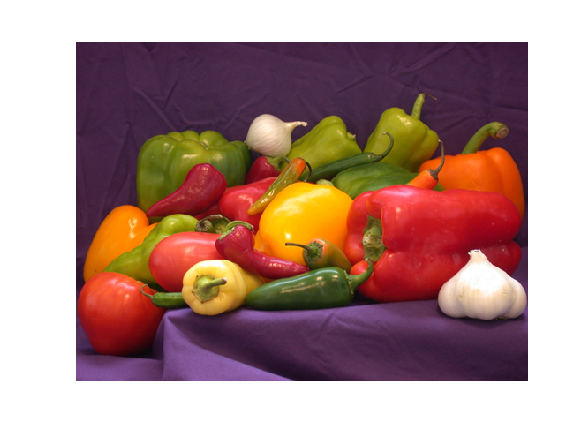

% Load in an image: 'peppers.png'. Hint: help imread
im = imread("peppers.png");

% Show the figure on the screen. Hint: help imshow
imshow(im);


% Resize the image for AlexNet requirements [227 227]. Hint: help imresize
imResized = imresize(im, [227 227]);

% Classify what the image is based on the AlexNet pretrained network
% Can you guess the function you need to classify your image?
label = classify(net, imResized);
label
% -> identified as "bell pepper" !

As you can see from the result, the network identified the above image as bell peppers.

*Copyright 2019 The MathWorks, Inc.*